# Amplitude axis operations

In this exercise you will see operations on 1D signals that affect the amplitude axis. You will also perform algebraic operations between unaligned signals by considering their respective time axis.

% Clear workspace and command window
clear;
clc;

## Sine signal

### Unit-frequency sine signal

You can use the command [sin](https://uk.mathworks.com/help/matlab/ref/sin.html) to generate a simple sine wave.

The custom function `gen_sin` generates and visualizes an analog and digital sine signal. The code for the function can be found at the end of the script (see section *Helper functions*).

Keeping the sine frequency at 1 results in an unit-frequency sine wave.

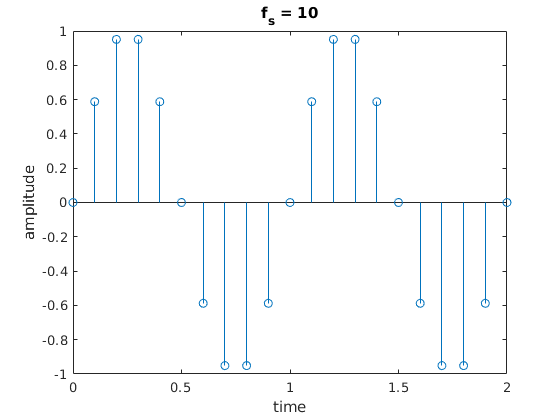

clear;clc;
fs = 10; % sampling frequency
D = 2;   % duration in seconds
[signal, n] = gen_sin(fs, D);  % unit frequency sine (i.e. 1 cycle per second)

## Amplitude offset

Add or subtract a bias to all the samples of the signal.

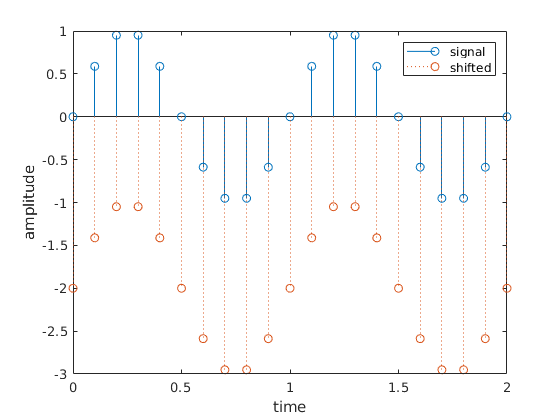

shift = -2; % set the constant
signal_bias = signal + shift; % sum the constant

% Visualization
figure; stem(n,signal);
hold on;
stem(n,signal_bias,':');
hold off;
xlabel('time'); ylabel('amplitude');
legend('signal', 'with offset');

## Attenuation and amplification

Multiply by a scalar all the samples of the signal.

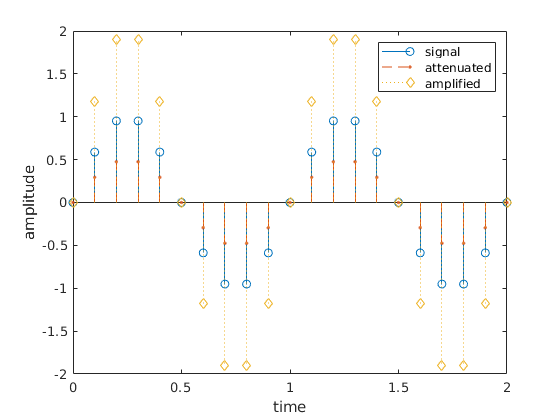

constant_factor = 2; % set a positive constant greater than or equal to 1
signal_att = signal / constant_factor;    % divide to attenuate
signal_ampl = signal * constant_factor;   % multiply to amplify

% Visualization
figure; stem(n,signal);
hold on;
stem(n,signal_att,'--s');
stem(n,signal_ampl,':d');
hold off;
xlabel('time'); ylabel('amplitude');
legend('signal', 'attenuated', 'amplified');

## Non-linear operations

### Half-wave and full-wave rectification

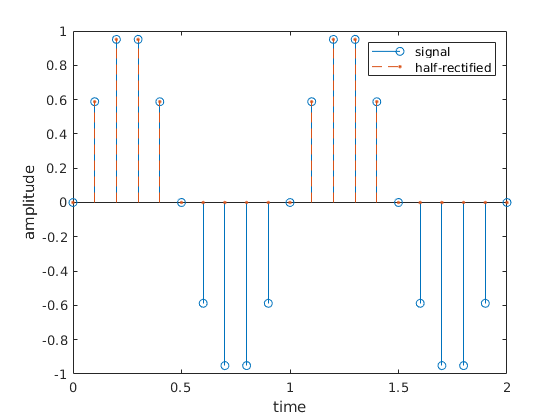

signal_half = signal .* (signal>0);     % half-wave rectification
signal_full = signal .* sign(signal);   % full-wave rectification

% Visualization of the half-wave rectified signal
figure; stem(n,signal);
hold on;
stem(n,signal_half,'--.');
hold off;
xlabel('time'); ylabel('amplitude');
legend('signal', 'half-rectified');

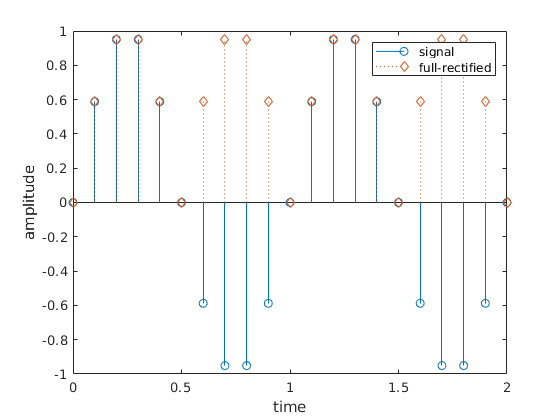


% Visualization of the full-wave rectified signal
figure; stem(n,signal);
hold on;
stem(n,signal_full,':d');
hold off;
xlabel('time'); ylabel('amplitude');
legend('signal', 'full-rectified');

### Power correction

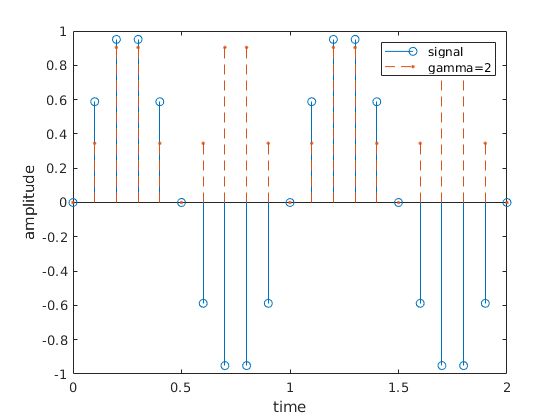

signal_power2 = signal .^ 2;    % power correction by 2
signal_power3 = signal .^ 3;    % power correction by 3

% Visualization of power=2
figure; stem(n,signal);
hold on;
stem(n,signal_power2,'--.');
hold off;
xlabel('time'); ylabel('amplitude');
legend('signal', 'power=2');

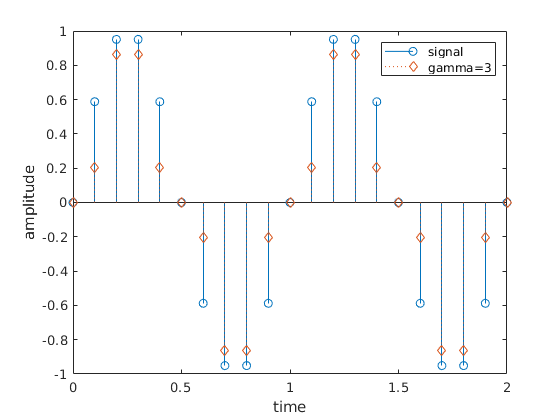


% Visualization of power=3
figure; stem(n,signal);
hold on;
stem(n,signal_power3,':d');
hold off;
xlabel('time'); ylabel('amplitude');
legend('signal', 'power=3');

## Algebraic operations between unaligned signals

Here we consider two signals with the same sampling frequency but different duration.

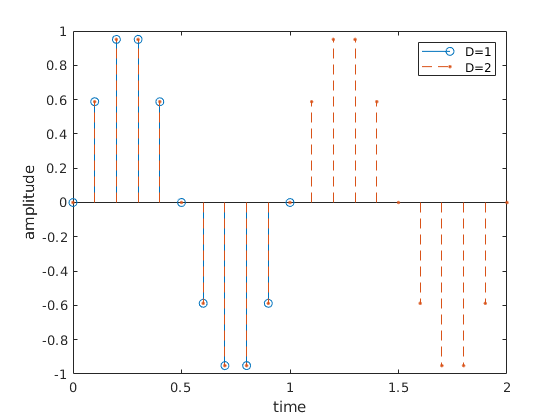

fs = 10; %  sampling frequency for both signals
D1 = 1; % duration of signal1
D2 = 2; % duration of signal2
[signal1, n1] = gen_sin(fs, D1, false); % first signal
[signal2, n2] = gen_sin(fs, D2, false); % second signal

% Visualization
figure; stem(n1,signal1);
hold on;
stem(n2,signal2,'--.');
hold off;
xlabel('time'); ylabel('amplitude');
legend('D=1', 'D=2');

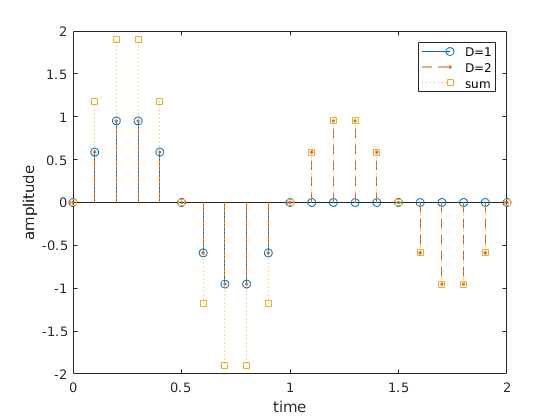


% Compute the extended time axis
n1 = round(n1, 10); n2 = round(n2, 10); % avoid approximation errors
n = unique([n1; n2]);                   % ordered full time axis
% Compute the zero-padded signal1 in the extended time axis
signal1_ext = zeros(size(n));
signal1_ext(ismember(n,n1)) = signal1;
% Compute the zero-padded signal2 in the extended time axis
signal2_ext = zeros(size(n));
signal2_ext(ismember(n,n2)) = signal2;
% Sum and product of signals having the same time axis
signal_sum = signal1_ext + signal2_ext;
signal_prod = signal1_ext .* signal2_ext;

% Visualization of sum
figure; stem(n,signal1_ext);
hold on;
stem(n,signal2_ext,'--.');
stem(n,signal_sum,':s');
hold off;
xlabel('time'); ylabel('amplitude');
legend('D=1', 'D=2', 'sum');

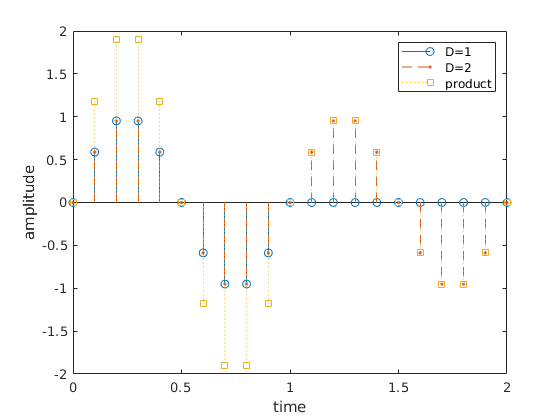


% Visualization of product
figure; stem(n,signal1_ext);
hold on;
stem(n,signal2_ext,'--.');
stem(n,signal_sum,':s');
hold off;
xlabel('time'); ylabel('amplitude');
legend('D=1', 'D=2', 'product');

Exercise:

Generate two signals with different sampling frequencies, then repeat the last section.

Note:

To align signals having different time sampling references, please refers to the "[Signal Processing Onramp](https://matlabacademy.mathworks.com/R2020b/portal.html?course=signalprocessing#chapter=3&lesson=3&section=1)" MATLAB course.

## Simple feature computation

In this section you will extract simple features that describe the periodic signal. Firstly, a sine is generated. Then, one period is extracted in the `signal_generator` array. Finally, the average value `A` and the power `P` of the periodic signal are computed.

[signal, n] = gen_sin(fs, D, false);
N = fs; % number of samples in each period equals to the fs for the unit-frequency sine
signal_generator = signal(1:N); % extract one period of the signal

% Average value
A = mean(signal_generator);
% Power
P = sum(signal_generator.^2)/N;

Exercise:

Generate a sine at a different frequency and repeat the computation of the average value and power.

## Helper functions

### Generate and visualize a sine signal

Samples a sinusoid with frequency equals to 1.

Inputs:

- `fs`: sampling frequency

- `D`: duration of total signal

- `plot_fig`: boolean flag [defaut: true]

Outputs:

- `signal`: y-values of the digital signal

- `n`: x-values of the digital signal

function [signal, n] = gen_sin(fs, D, plot_fig)
% Samples a sinusoid with frequency equals to 1.
% Inputs:
% - fs: sampling frequency
% - D: duration
% - plot_fig: boolean flag [defaut: true]
if nargin<3 || isempty(plot_fig), plot_fig=true; end
n = (0:1/fs:D)';      % time axis
signal = sin(2*pi*n); % samples
if plot_fig
    figure; stem(n,signal);
    xlabel('time'); ylabel('amplitude');
    title(sprintf('f_s = %g', fs));
end
end

Check out the Signal Analyzer tool presentation in the "[Signal Processing Onramp](https://matlabacademy.mathworks.com/R2020b/portal.html?course=signalprocessing#chapter=2&lesson=6&section=1)" MATLAB course.